## Preliminaries and Data Selection

listing = dir("AllfERNSpikeFiles"); 
listing = struct2table(listing);
session_ids = listing.name(~listing.isdir); 

% skip sessions 10/15/16 bc of weird iFR stuff
% skip sessions 3/11/12/13 bc of not recording P25/50/75
good_sessions = readmatrix("good_sessions.csv"); 
session_ids = string(session_ids(good_sessions));

load("SwitchTrials.mat", "SwTrial"); 
trial_esps = SwTrial(good_sessions, 2); 
clear listing good_sessions SwTrial

## PCA Reproduction: Fig. 2A

top3_pcs = cell(length(session_ids), 4); 
for i = 1 : length(session_ids) 
    [filtered_and_avgd_iFRs, np_ports] = filter_and_avg_iFRs(i, session_ids); 
    [coeff, score, ~, ~, explained, ~] = pca(filtered_and_avgd_iFRs); 
    top3_pcs{i, 1} = i; 
    top3_pcs{i, 2} = np_ports; 
    top3_pcs{i, 3} = coeff(:, 1:3); 
    top3_pcs{i, 4} = score(:, 1:3); 
    top3_pcs{i, 5} = explained(1:3); 
    clear filtered_and_avgd_iFRs np_ports coeff score explained
end

total_explained = zeros(length(session_ids), 1); 
for i = 1 : length(session_ids)
    total_explained(i) = sum(top3_pcs{i, 5}); 
end
disp("Average total explained: " + mean(total_explained))

Average total explained: 53.457


disp("Reported total explained: " + 20.8)

Reported total explained: 20.8


scores_by_port = cell(length(session_ids), 4); 
for i = 1 : length(session_ids)
    scores_by_port{i, 1} = i; 
    [sbp25, sbp50, sbp75] = score_by_port(i, top3_pcs, session_ids, trial_esps);
    scores_by_port{i, 2} = sbp25; 
    scores_by_port{i, 3} = sbp50; 
    scores_by_port{i, 4} = sbp75; 
end

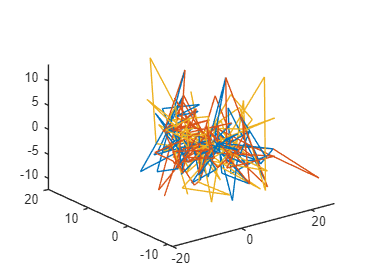

% visualize 3d plot for session 2
sbp25 = scores_by_port{2, 2};
sbp50 = scores_by_port{2, 3}; 
sbp75 = scores_by_port{2, 4}; 
plot3(sbp25(:, 1), sbp25(:, 2), sbp25(:, 3), ...
      sbp50(:, 1), sbp50(:, 2), sbp50(:, 3), ...
      sbp75(:, 1), sbp75(:, 2), sbp50(:, 3))

function [filtered_and_avgd_iFRs, np_ports] = filter_and_avg_iFRs(i, session_ids)
    load("AllfERNSpikeFiles/" + session_ids(i), "Event_timestamps", "iFR", "Tmtx");
    start = Tmtx(1); 
    sr = 1 / (Tmtx(2) - start); 

    np_event_mask = ismember(Event_timestamps(:, 3), 1:3); 
    np_intervals = Event_timestamps(np_event_mask, 1:2);
    np_ports = Event_timestamps(np_event_mask, 3); 
    
    filtered_and_avgd_iFRs = zeros(size(np_intervals, 1), size(iFR, 1));
    for trial = 1 : size(np_intervals, 1)
        start_tmtx = floor((np_intervals(trial, 1) - start) * sr); 
        end_tmtx = floor((np_intervals(trial, 2) - start) * sr); 
        filtered_and_avgd_iFRs(trial, :) = mean(iFR(:, start_tmtx:end_tmtx), 2)'; 
    end
    clearvars -except filtered_and_avgd_iFRs np_ports
end

function [sbp25, sbp50, sbp75] = score_by_port(i, top3_pcs, session_ids, trial_esps)
    load("AllfERNSpikeFiles/" + session_ids(i), "Event_timestamps", "P25", "P50", "P75");
    trial_esp = trial_esps(i);
    p25_port = P25; 
    p50_port = P50; 
    p75_port = P75; 
    
    np_event_mask = ismember(Event_timestamps(:, 3), 1:3); 
    np_ports = Event_timestamps(np_event_mask, 3);

    trials25 = find(np_ports(1:trial_esp-1) == p25_port); 
    trials25 = [trials25; (find(np_ports(trial_esp:end) == p75_port))];

    trials50 = find(np_ports == p50_port);

    trials75 = find(np_ports(1:trial_esp-1) == p75_port);
    trials75 = [trials75; (find(np_ports(trial_esp:end) == p25_port))];
    
    pca_scores = top3_pcs{i, 4}; 
    sbp25 = pca_scores(trials25, :); 
    sbp50 = pca_scores(trials50, :); 
    sbp75 = pca_scores(trials75, :); 
    clearvars -except sbp25 sbp50 sbp75
end